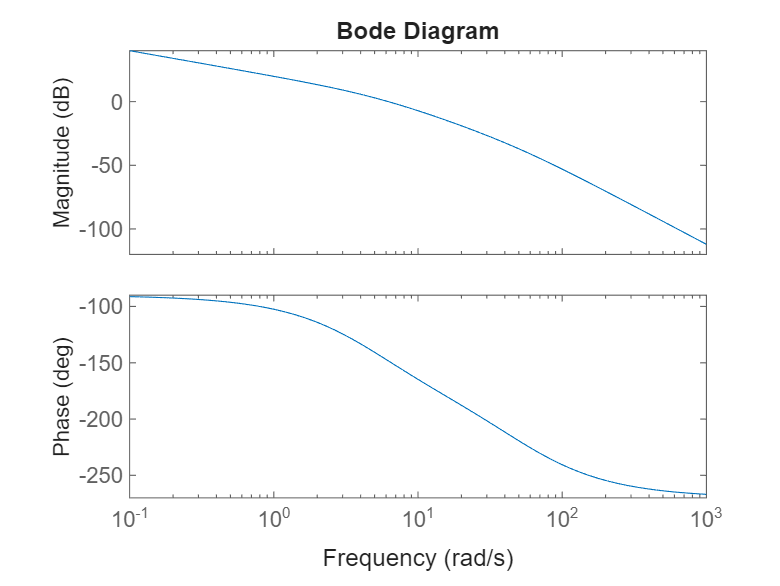

s = tf("s");
G = 1/((s/5+1)*(s/50+1));
K = 10;
K_control = K/s;
bode(K_control*G)

wg_prima = 4.13; % rad/s
GM_wg_prima = 5.5; % dB
a = 10^(-GM_wg_prima / 20);
T1 = 10 / (a*wg_prima);

% Lag phase
C = (1+a*T1*s)/(1+T1*s);
a, T1, C

a = 0.5309

T1 = 4.5609


C =
 
  2.421 s + 1
  -----------
  4.561 s + 1
 
Continuous-time transfer function.
Model Properties


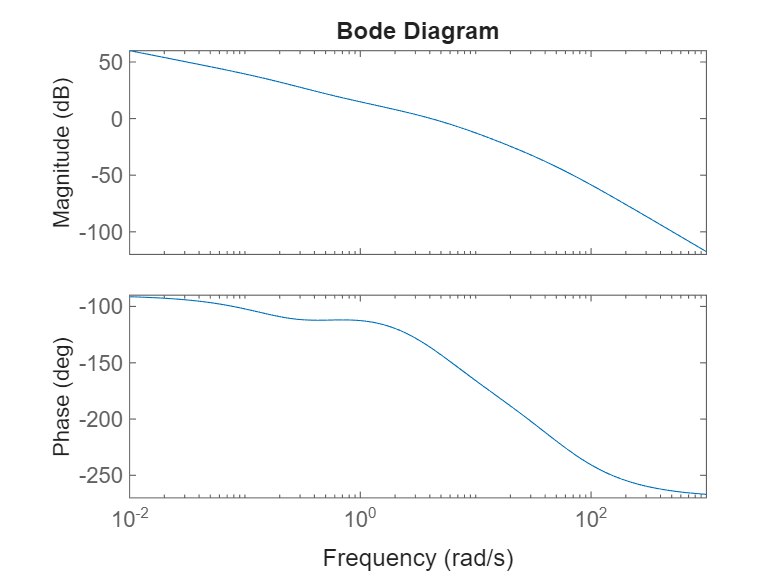

bode(K_control*C*G);

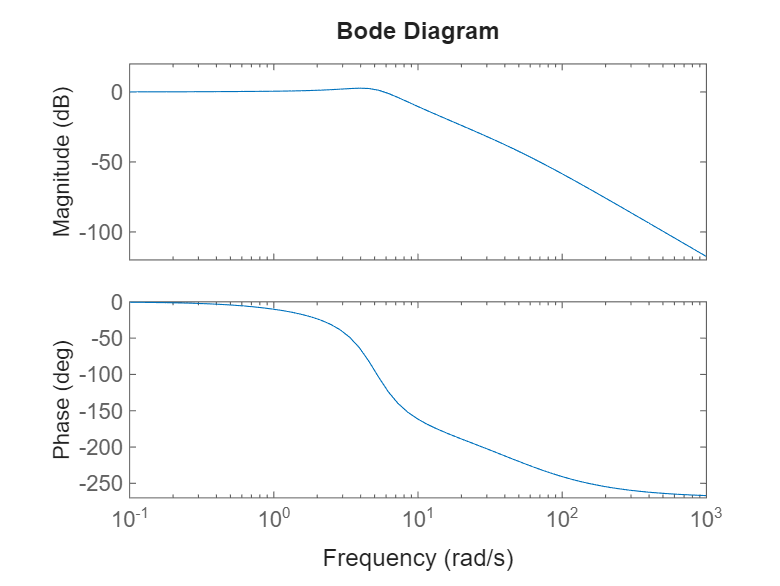

Go = feedback(K_control*C*G, 1);
% Analizar a bajas frecuencias ancho de banda
bode(Go);

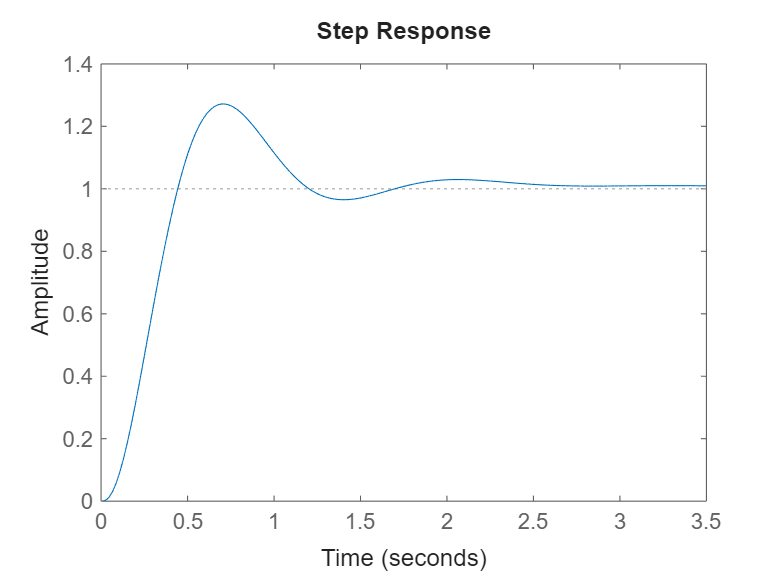


% Para analizar
step(Go);

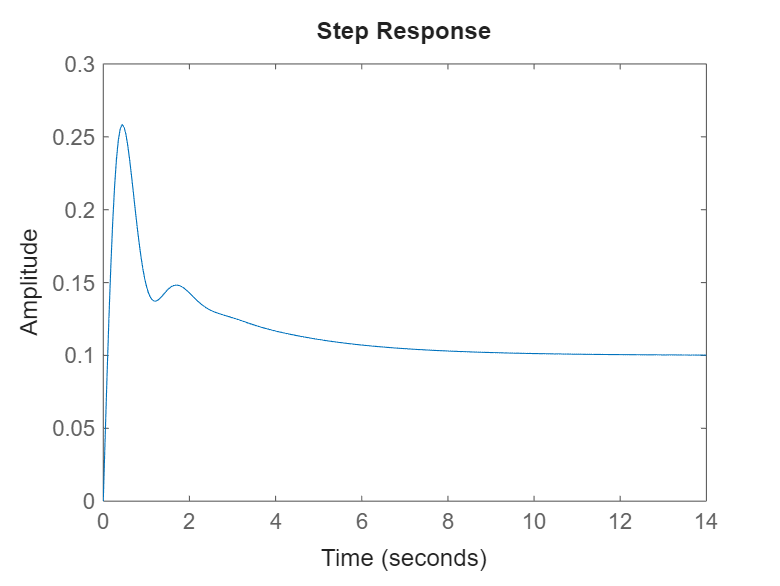

step(1/s - Go/s);

% Red de adelanto
mf_req = 40;
mf_fact = 31.7;


theta_m = mf_req - mf_fact + 5;
b = (1+sind(theta_m))/(1-sind(theta_m));
freq_revision = 10*log10(b);
frecuencias = logspace(-1, 2, 200)

frecuencias =     0.1000    0.1035    0.1072    0.1110    0.1149    0.1190    0.1232    0.1275    0.1320    0.1367    0.1415    0.1465    0.1517    0.1570    0.1626    0.1683    0.1743    0.1804    0.1868    0.1934    0.2002    0.2073    0.2146    0.2222    0.2300    0.2382    0.2466    0.2553    0.2643    0.2736    0.2833    0.2933    0.3037    0.3144    0.3255    0.3370    0.3489    0.3612    0.3740    0.3872    0.4009    0.4150    0.4297    0.4449    0.4606    0.4769    0.4937    0.5111    0.5292    0.5479


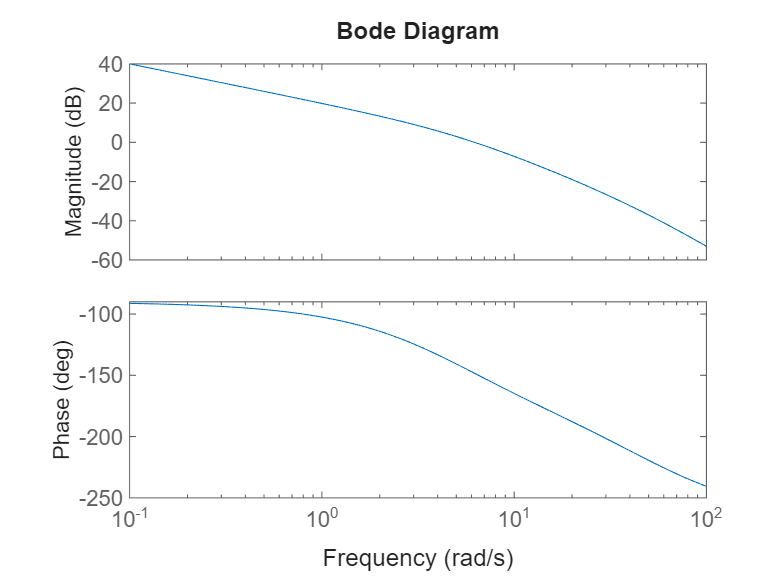

bode(K_control * G, frecuencias);


theta_m, b, freq_revision

theta_m = 13.3000

b = 1.5976

freq_revision = 2.0346

wg_prima_adelanto = 7.15 % rad/s

wg_prima_adelanto = 7.1500

T2 = 1/(sqrt(b)*wg_prima_adelanto);
C2 = (1 + b*T2*s)/(1 + T2*s);

wg_prima_adelanto, T2, C2

wg_prima_adelanto = 7.1500

T2 = 0.1107


C2 =
 
  0.1768 s + 1
  ------------
  0.1107 s + 1
 
Continuous-time transfer function.
Model Properties


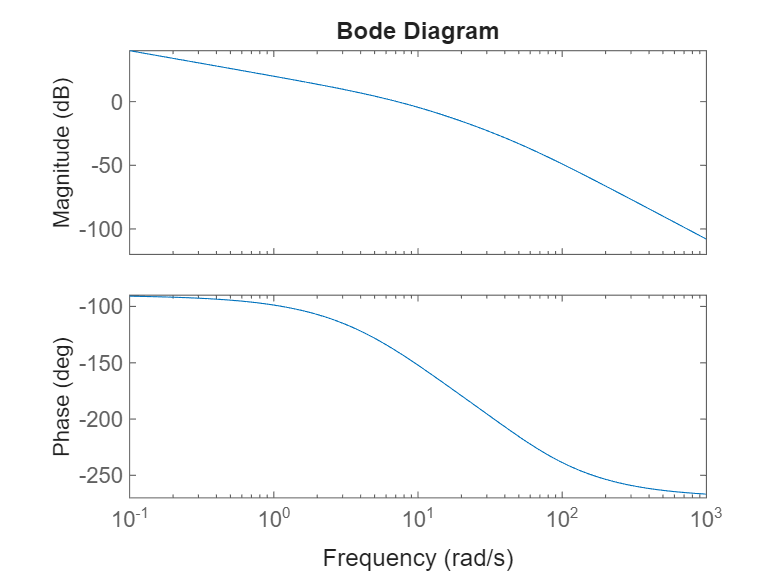

bode(K_control*C2*G)

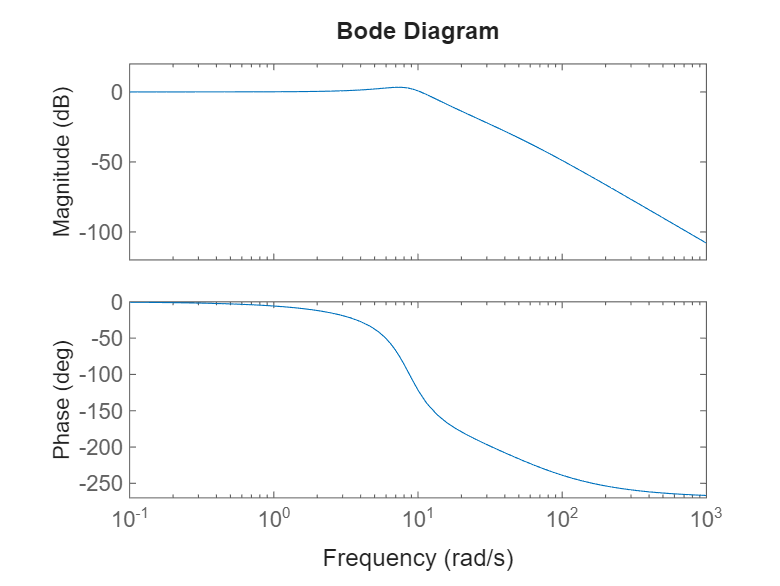

Go_adelanto = feedback(K_control*C2*G, 1);
bode(Go_adelanto);

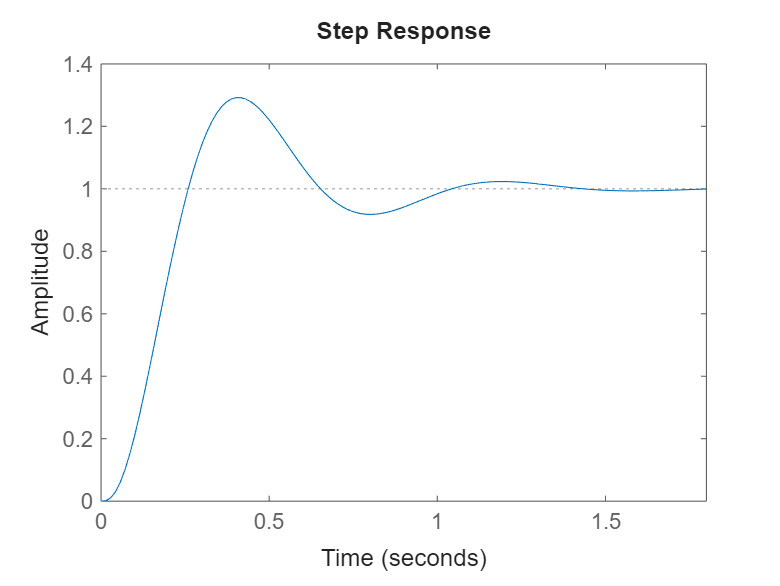

step(Go_adelanto);

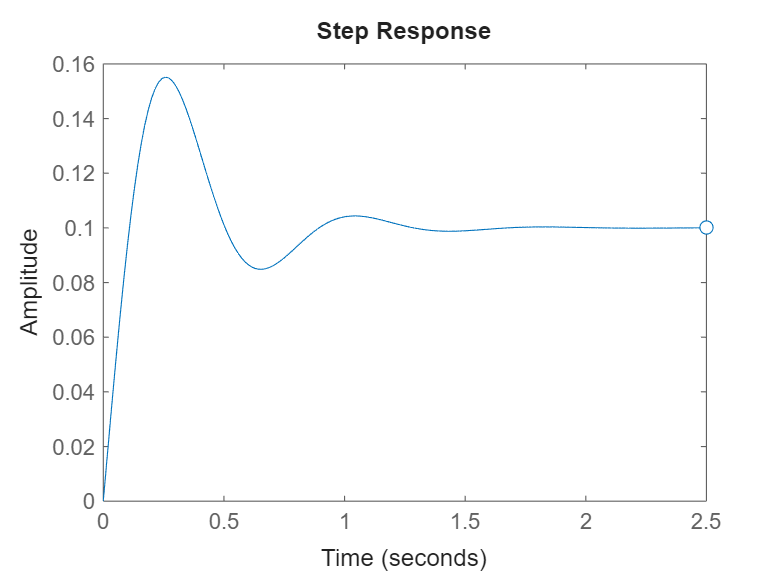

step(1/s-Go_adelanto/s);